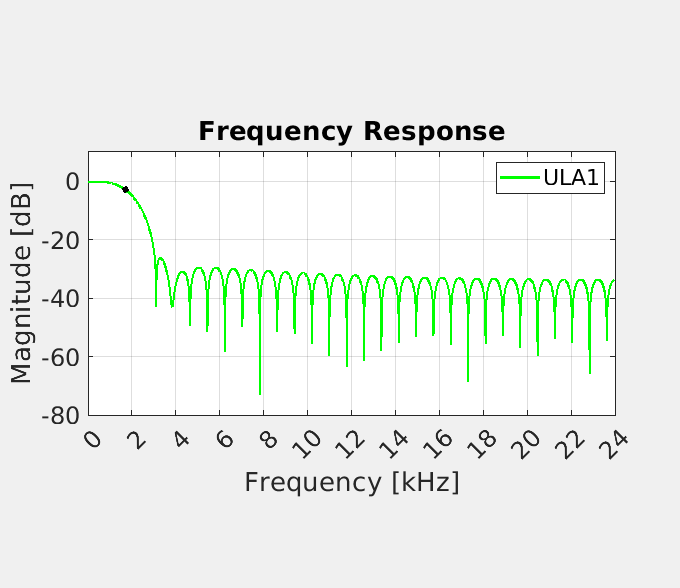

clc
clear
close all

fs = 48e3;
c = 1496;

cfULA1 = 1700;
cfULA2 = [cfULA1 4500];
cfULA3 = cfULA2(2);

FIRULA1 = makeFIR(cfULA1, 60, fs, 'low');
FIRULA2 = makeFIR(cfULA2, 60, fs, 'bandpass');
FIRULA3 = makeFIR(cfULA3, 60, fs, 'high');

% FIRULA1 = fir1(60, 2*cfULA1/fs, 'low');
% FIRULA2 = fir1(60, 2*cfULA2/fs, 'bandpass');
% FIRULA3 = fir1(60, 2*cfULA3/fs, 'high');

%freqz(FIRULA1,1,1024,fs);

[HULA1,w] = freqz(FIRULA1,1,1024*4,fs);
[HULA2,w] = freqz(FIRULA2,1,1024*4,fs);
[HULA3,w] = freqz(FIRULA3,1,1024*4,fs);

figure(1)
set(gcf,'Visible','on', 'Units', 'centimeters',...
          'OuterPosition', [0 0 18 18])
plot(w,10*log10(abs(HULA1)), 'Color', 'g', 'LineWidth',2);
hold on
plot(cfULA1,-3,'o', 'MarkerSize',4, 'Color', 'black', 'MarkerFaceColor', 'black')
title('Frequency Response', 'FontSize', 22)
xlabel('Frequency [kHz]', 'FontSize', 20)
ylabel('Magnitude [dB]', 'FontSize', 20)
ylim([-80 10])
xlim([0 fs/2])
ytickList = linspace(-80,10,10);
yticks(ytickList(1:2:end))
yticklabels(string(ytickList(1:2:end)))
xtickList = linspace(0,24e3,24+1);
xticks(xtickList(1:2:end))
xticklabels(string(xtickList(1:2:end)/1000))
ax = gca;
ax.FontSize = 18;
pbaspect([2 1 1])
legend('ULA1')%,'Position', [0.31 0.15 1 1])
grid
hold off
%exportgraphics(gcf,'FreqResULA1.pdf')

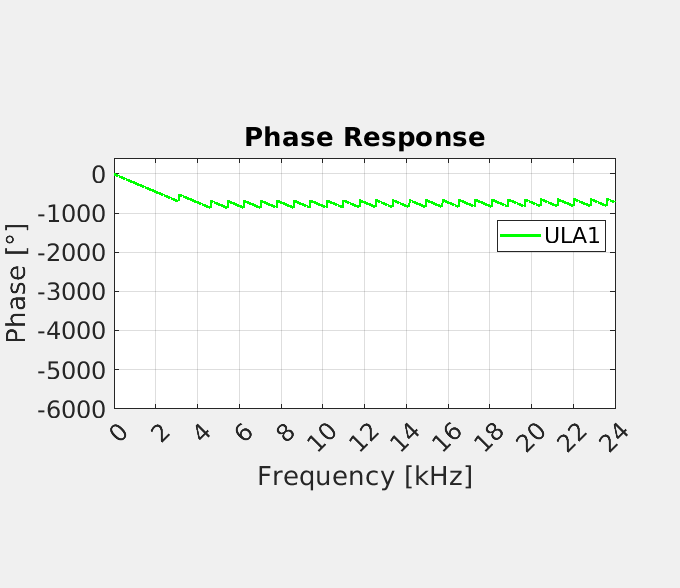


figure(2)
set(gcf,'Visible','on', 'Units', 'centimeters',...
          'OuterPosition', [0 0 18 18])
plot(w,180/pi*unwrap(angle(HULA1)), 'Color', 'g', 'LineWidth',2);
hold on
title('Phase Response', 'FontSize', 22)
xlabel('Frequency [kHz]', 'FontSize', 20)
ylabel('Phase [°]', 'FontSize', 20)
ylim([-6000 400])
xlim([0 fs/2])
ytickList = linspace(-6000,0,13);
yticks(ytickList(1:2:end))
yticklabels(string(ytickList(1:2:end)))
xtickList = linspace(0,24e3,24+1);
xticks(xtickList(1:2:end))
xticklabels(string(xtickList(1:2:end)/1000))
ax = gca;
ax.FontSize = 18;
legend('ULA1', 'Position', [0.31 0.1 1 1])
pbaspect([2 1 1])
grid
xlim([0 fs/2])
hold off
%exportgraphics(gcf,'PhaseResULA1.pdf')

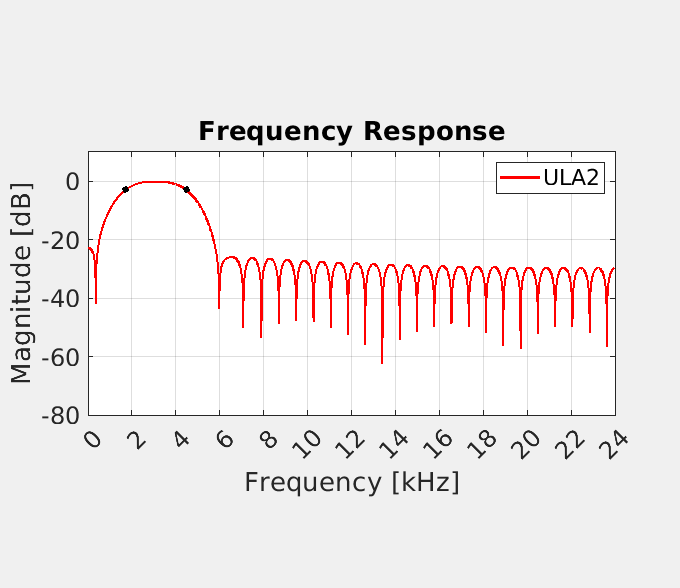


figure(3)
set(gcf,'Visible','on', 'Units', 'centimeters',...
          'OuterPosition', [0 0 18 18])
plot(w,10*log10(abs(HULA2)), 'Color', 'r', 'LineWidth',2);
hold on
plot(cfULA2,-3,'o', 'MarkerSize',4, 'Color', 'black', 'MarkerFaceColor', 'black')
%plot(4500,-3,'o', 'MarkerSize',4, 'Color', 'black', 'MarkerFaceColor', 'black')
title('Frequency Response', 'FontSize', 22)
xlabel('Frequency [kHz]', 'FontSize', 20)
ylabel('Magnitude [dB]', 'FontSize', 20)
ylim([-80 10])
xlim([0 fs/2])
ytickList = linspace(-80,10,10);
yticks(ytickList(1:2:end))
yticklabels(string(ytickList(1:2:end)))
xtickList = linspace(0,24e3,24+1);
xticks(xtickList(1:2:end))
xticklabels(string(xtickList(1:2:end)/1000))
ax = gca;
ax.FontSize = 18;
pbaspect([2 1 1])
legend('ULA2')%,'Position', [0.31 0.15 1 1])
grid
hold off
%exportgraphics(gcf,'FreqResULA2.pdf')

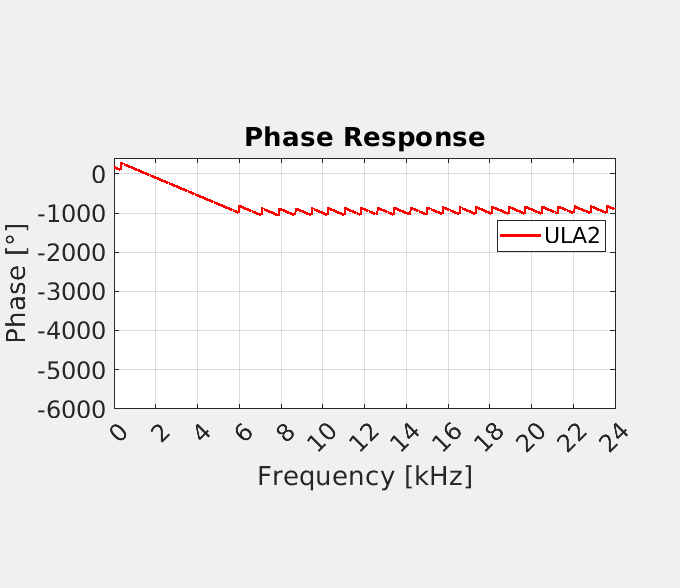




figure(4)
set(gcf,'Visible','on', 'Units', 'centimeters',...
          'OuterPosition', [0 0 18 18])
plot(w,180/pi*unwrap(angle(HULA2)), 'Color', 'r', 'LineWidth',2);
hold on
title('Phase Response', 'FontSize', 22)
xlabel('Frequency [kHz]', 'FontSize', 20)
ylabel('Phase [°]', 'FontSize', 20)
ylim([-6000 400])
xlim([0 fs/2])
ytickList = linspace(-6000,0,13);
yticks(ytickList(1:2:end))
yticklabels(string(ytickList(1:2:end)))
xtickList = linspace(0,24e3,24+1);
xticks(xtickList(1:2:end))
xticklabels(string(xtickList(1:2:end)/1000))
ax = gca;
ax.FontSize = 18;
legend('ULA2', 'Position', [0.31 0.1 1 1])
pbaspect([2 1 1])
grid
xlim([0 fs/2])
hold off
%exportgraphics(gcf,'PhaseResULA2.pdf')

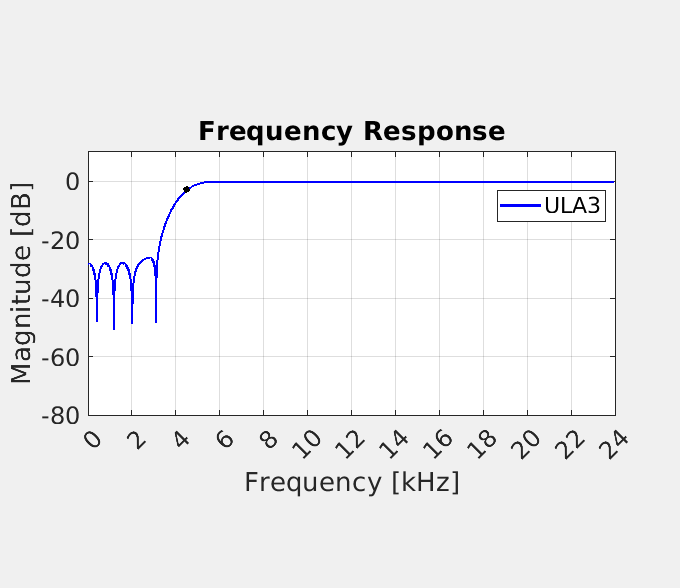


figure(5)
set(gcf,'Visible','on', 'Units', 'centimeters',...
          'OuterPosition', [0 0 18 18])
plot(w,10*log10(abs(HULA3)), 'Color', 'b', 'LineWidth',2);
hold on
plot(cfULA3,-3,'o', 'MarkerSize',4, 'Color', 'black', 'MarkerFaceColor', 'black')
title('Frequency Response', 'FontSize', 22)
xlabel('Frequency [kHz]', 'FontSize', 20)
ylabel('Magnitude [dB]', 'FontSize', 20)
ylim([-80 10])
xlim([0 fs/2])
ytickList = linspace(-80,10,10);
yticks(ytickList(1:2:end))
yticklabels(string(ytickList(1:2:end)))
xtickList = linspace(0,24e3,24+1);
xticks(xtickList(1:2:end))
xticklabels(string(xtickList(1:2:end)/1000))
ax = gca;
ax.FontSize = 18;
pbaspect([2 1 1])
legend('ULA3', 'Position', [0.31 0.15 1 1])
grid
hold off
%exportgraphics(gcf,'FreqResULA3.pdf')

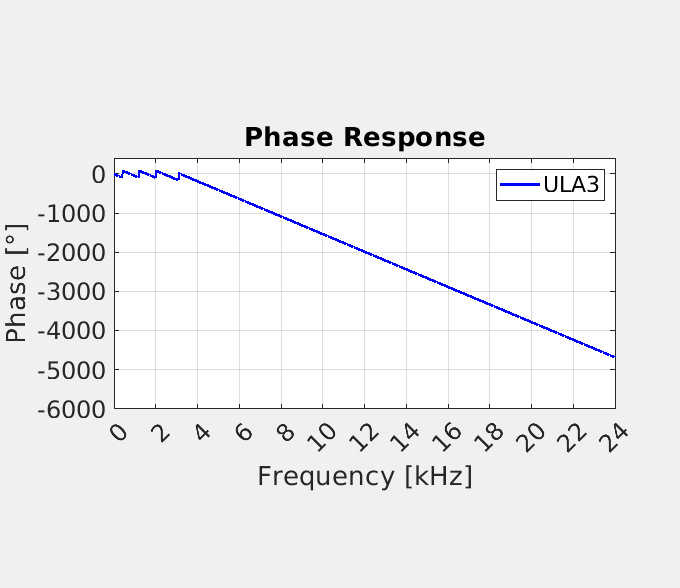




figure(6)
set(gcf,'Visible','on', 'Units', 'centimeters',...
          'OuterPosition', [0 0 18 18])
plot(w,180/pi*unwrap(angle(HULA3)), 'Color', 'b', 'LineWidth',2);
hold on
title('Phase Response', 'FontSize', 22)
xlabel('Frequency [kHz]', 'FontSize', 20)
ylabel('Phase [°]', 'FontSize', 20)
ylim([-6000 400])
xlim([0 fs/2])
ytickList = linspace(-6000,0,13);
yticks(ytickList(1:2:end))
yticklabels(string(ytickList(1:2:end)))
xtickList = linspace(0,24e3,24+1);
xticks(xtickList(1:2:end))
xticklabels(string(xtickList(1:2:end)/1000))
ax = gca;
ax.FontSize = 18;
legend('ULA3')%, 'Position', [0.31 0.1 1 1])
pbaspect([2 1 1])
grid
xlim([0 fs/2])
hold off
%exportgraphics(gcf,'PhaseResULA3.pdf')

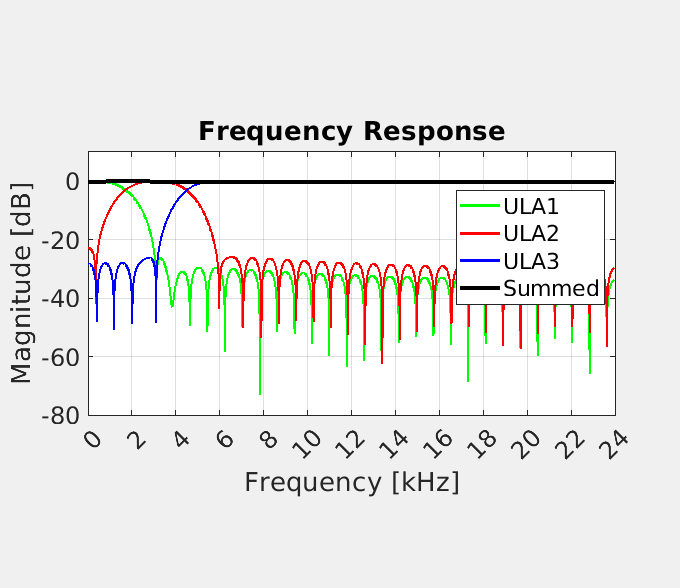



figure(7)
set(gcf,'Visible','on', 'Units', 'centimeters',...
          'OuterPosition', [0 0 18 18])
plot(w,10*log10(abs(HULA1)), 'Color', 'g', 'LineWidth',2);
hold on
plot(w,10*log10(abs(HULA2)), 'Color', 'r', 'LineWidth',2);
plot(w,10*log10(abs(HULA3)), 'Color', 'b', 'LineWidth',2);
plot(w,10*log10(abs(HULA1+HULA2+HULA3)), 'Color', 'black', 'LineWidth',3, 'LineStyle', '-');
title('Frequency Response', 'FontSize', 22)
xlabel('Frequency [kHz]', 'FontSize', 20)
ylabel('Magnitude [dB]', 'FontSize', 20)
ylim([-80 10])
xlim([0 fs/2])
ytickList = linspace(-80,10,10);
yticks(ytickList(1:2:end))
yticklabels(string(ytickList(1:2:end)))
xtickList = linspace(0,24e3,24+1);
xticks(xtickList(1:2:end))
xticklabels(string(xtickList(1:2:end)/1000))
ax = gca;
ax.FontSize = 18;
pbaspect([2 1 1])
legend('ULA1', 'ULA2', 'ULA3', 'Summed', 'Position', [0.28 0.08 1 1])
grid
hold off
%exportgraphics(gcf,'FreqResSum.pdf')

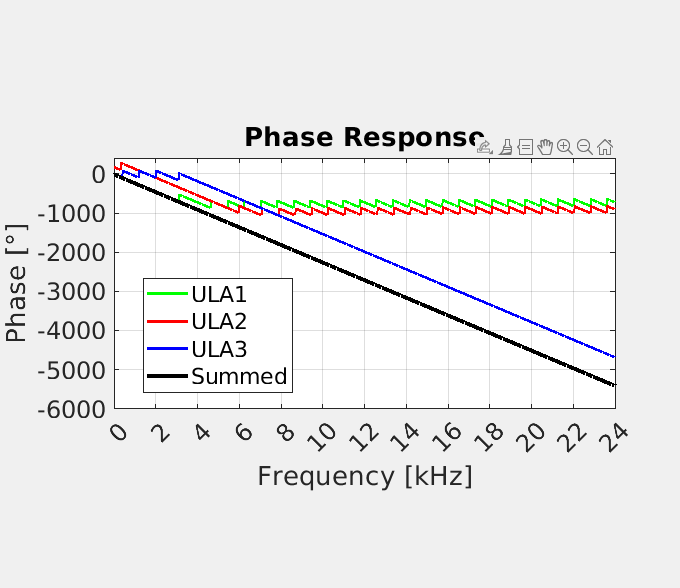


figure(8)
set(gcf,'Visible','on', 'Units', 'centimeters',...
          'OuterPosition', [0 0 18 18])
plot(w,180/pi*unwrap(angle(HULA1)), 'Color', 'g', 'LineWidth',2);
hold on
plot(w,180/pi*unwrap(angle(HULA2)), 'Color', 'r', 'LineWidth',2);
plot(w,180/pi*unwrap(angle(HULA3)), 'Color', 'b', 'LineWidth',2);
plot(w,180/pi*unwrap(angle(HULA1+HULA2+HULA3)), 'Color', 'black', 'LineWidth',3);
title('Phase Response', 'FontSize', 22)
xlabel('Frequency [kHz]', 'FontSize', 20)
ylabel('Phase [°]', 'FontSize', 20)
ylim([-6000 400])
xlim([0 fs/2])
ytickList = linspace(-6000,0,13);
yticks(ytickList(1:2:end))
yticklabels(string(ytickList(1:2:end)))
xtickList = linspace(0,24e3,24+1);
xticks(xtickList(1:2:end))
xticklabels(string(xtickList(1:2:end)/1000))
ax = gca;
ax.FontSize = 18;
legend('ULA1', 'ULA2', 'ULA3', 'Summed', 'Position', [-0.18 -0.07 1 1])
pbaspect([2 1 1])
grid
xlim([0 fs/2])
hold off
%exportgraphics(gcf,'PhaseResSum.pdf')

% Get the dimensions of the matrix
FIR1Length = length(FIRULA1);
FIR2Length = length(FIRULA2);
FIR3Length = length(FIRULA3);

% Open the header file for writing
%fid_h = fopen('DAS/main/FIRWeights.h', 'w');
fid_h = fopen('ESP32/SplashDetect/main/FIRWeights.h', 'w');


% Write the header file contents
%fprintf(fid_h, '#include <complex.h>\n\n');
fprintf(fid_h, '#ifndef FIRWEIGHTS_H\n');
fprintf(fid_h, '#define FIRWEIGHTS\n\n');

fprintf(fid_h, '#define FIR1LENGTH %d\n', FIR1Length);
fprintf(fid_h, '#define FIR2LENGTH %d\n', FIR2Length);
fprintf(fid_h, '#define FIR3LENGTH %d\n\n', FIR3Length);
fprintf(fid_h, 'static __attribute__((aligned(16))) float FIR1WEIGHTS[FIR1LENGTH] = \n\t{');
for r = 1:FIR1Length
    fprintf(fid_h, '%f', cast(FIRULA1(r),"single"));
    if r < FIR1Length
        fprintf(fid_h, ',');
    end
end
fprintf(fid_h, '};\n\n');

fprintf(fid_h, 'static __attribute__((aligned(16))) float FIR2WEIGHTS[FIR2LENGTH] = \n\t{');
for r = 1:FIR2Length
    fprintf(fid_h, '%f', cast(FIRULA2(r),"single"));
    if r < FIR2Length
        fprintf(fid_h, ',');
    end
end
fprintf(fid_h, '};\n\n');


fprintf(fid_h, 'static __attribute__((aligned(16))) float FIR3WEIGHTS[FIR3LENGTH] = \n\t{');
for r = 1:FIR3Length
    fprintf(fid_h, '%f', cast(FIRULA3(r),"single"));
    if r < FIR3Length
        fprintf(fid_h, ',');
    end
end
fprintf(fid_h, '};\n\n');

fprintf(fid_h, '#endif // FIRWEIGHTS_H\n');

% Close the header file
fclose(fid_h);

disp('Header file generated successfully.');

Header file generated successfully.


function coeffs_adjusted = makeFIR(Fc, order, fs, type)
if ~exist('type', 'var') 
    coeffs = fir1(order,2*Fc/fs);
else 
    coeffs = fir1(order,2*Fc/fs, type);
end 
[mag, freq] = freqz(coeffs,1,1024,fs);
magdB = 10*log10(abs(mag));
if length(Fc) == 1
    [~, minIndex] = min(abs(magdB + 3));
    Fc_3dB = freq(minIndex);
    Fc_adjusted = Fc * (Fc/Fc_3dB);
    coeffs_adjusted = fir1(order, 2*Fc_adjusted/fs, type);
elseif length(Fc) == 2
    %[~, minIndexLow] = min(abs(magdB + 3));
    minIndexLow = find(abs(magdB)<3,1);
    minIndexHigh = find(abs(magdB(minIndexLow:end))>3,1) + minIndexLow;
    FcLow_3dB = freq(minIndexLow);
    FcHigh_3dB = freq(minIndexHigh);
    FcLow_adjusted = Fc(1) * (Fc(1)/FcLow_3dB);
    FcHigh_adjusted = Fc(2) * (Fc(2)/FcHigh_3dB);
    coeffs_adjusted = fir1(order, 2*[FcLow_adjusted FcHigh_adjusted]/fs, type);
else
    disp("nederen")
end
end